clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater';
cd(workingpath);

files=dir('*top.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-8),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201001_top.csv


   56.2673  125.4151  194.5630   64.4272   98.1361  131.8450



吲哚_R_20200930_top.csv


   54.2995  122.3422  190.3850   67.1329  102.1270  137.1210



异戊酸_L_20200929_top.csv


   53.1225  121.6917  190.2610   66.0996   99.3773  132.6550



异戊酸_R_20200926_top.csv


   95.9620  148.8110  201.6600   79.4112  108.2996  137.1880



白桃_L_20201003_top.csv


   55.9635  124.9228  193.8820   56.6824   95.3447  134.0070



白桃_R_20201004_top.csv


   56.4970  125.4910  194.4850   55.4538   92.7459  130.0380



香蕉_L_20201008_top.csv


   66.3677  128.3604  190.3530   60.8057   95.2284  129.6510



香蕉_R_20201009_top.csv


   56.7712  139.0971  221.4230   51.9538   95.0794  138.2050



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 2.4300e+04
          df: 1
       edges: [0 100 200]
           O: [69045 22007]
           E: [45526 45526]


    90   110



pvalue = 0

st =     chi2stat: 2.6821e+04
          df: 1
       edges: [0 100 200]
           O: [67539 19283]
           E: [43411 43411]


    80   120



pvalue = 0

st =     chi2stat: 2.8201e+04
          df: 1
       edges: [0 100 200]
           O: [66179 17578]
           E: [4.1878e+04 4.1878e+04]


吲哚-R-2020093


   100   100



pvalue = 0

st =     chi2stat: 9.2685e+03
          df: 1
       edges: [0 100 200]
           O: [60440 31283]
           E: [4.5862e+04 4.5862e+04]


    90   110



pvalue = 0

st =     chi2stat: 9.4008e+03
          df: 1
       edges: [0 100 200]
           O: [55282 27402]
           E: [41342 41342]


    80   120



pvalue = 0

st =     chi2stat: 8.9671e+03
          df: 1
       edges: [0 100 200]
           O: [50503 24559]
           E: [37531 37531]


异戊酸-L-2020092


   100   100



pvalue = 0

st =     chi2stat: 2.2411e+04
          df: 1
       edges: [0 100 200]
           O: [67536 22593]
           E: [4.5064e+04 4.5064e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.2715e+04
          df: 1
       edges: [0 100 200]
           O: [64180 20359]
           E: [4.2270e+04 4.2270e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.1880e+04
          df: 1
       edges: [0 100 200]
           O: [59330 18155]
           E: [3.8742e+04 3.8742e+04]


异戊酸-R-2020092


   100   100



pvalue = 0

st =     chi2stat: 8.0411e+03
          df: 1
       edges: [0 100 200]
           O: [63352 35201]
           E: [4.9276e+04 4.9276e+04]


    90   110



pvalue = 0

st =     chi2stat: 7.5419e+03
          df: 1
       edges: [0 100 200]
           O: [61033 34229]
           E: [47631 47631]


    80   120



pvalue = 0

st =     chi2stat: 7.5911e+03
          df: 1
       edges: [0 100 200]
           O: [56677 30894]
           E: [4.3786e+04 4.3786e+04]


白桃-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 1.0551e+04
          df: 1
       edges: [0 100 200]
           O: [61755 30548]
           E: [4.6152e+04 4.6152e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.3551e+04
          df: 1
       edges: [0 100 200]
           O: [60145 25982]
           E: [4.3064e+04 4.3064e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.5703e+04
          df: 1
       edges: [0 100 200]
           O: [58676 22888]
           E: [40782 40782]


白桃-R-2020100


   100   100



pvalue = 0

st =     chi2stat: 1.5235e+04
          df: 1
       edges: [0 100 200]
           O: [69967 30788]
           E: [5.0378e+04 5.0378e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7402e+04
          df: 1
       edges: [0 100 200]
           O: [66798 26504]
           E: [46651 46651]


    80   120



pvalue = 0

st =     chi2stat: 1.9189e+04
          df: 1
       edges: [0 100 200]
           O: [64957 23709]
           E: [44333 44333]


香蕉-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 2.1324e+04
          df: 1
       edges: [0 100 200]
           O: [68432 24029]
           E: [4.6230e+04 4.6230e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.3610e+04
          df: 1
       edges: [0 100 200]
           O: [65810 20633]
           E: [4.3222e+04 4.3222e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.4477e+04
          df: 1
       edges: [0 100 200]
           O: [63603 18715]
           E: [41159 41159]


香蕉-R-2020100


   100   100



pvalue = 9.0705e-58

st =     chi2stat: 256.6827
          df: 1
       edges: [0 100 200]
           O: [47511 42699]
           E: [45105 45105]


    90   110



pvalue = 4.4497e-43

st =     chi2stat: 189.3312
          df: 1
       edges: [0 100 200]
           O: [45167 41125]
           E: [43146 43146]


    80   120



pvalue = 1.5867e-19

st =     chi2stat: 81.6965
          df: 1
       edges: [0 100 200]
           O: [42157 39573]
           E: [40865 40865]


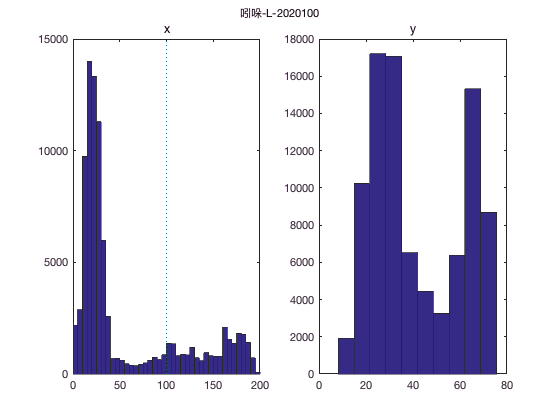

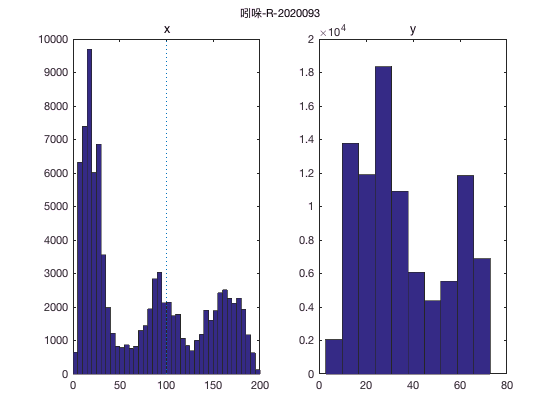

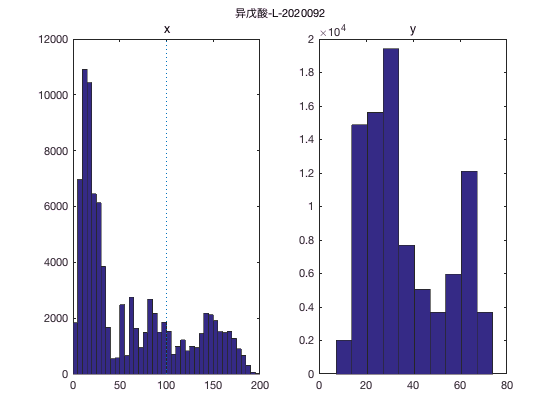

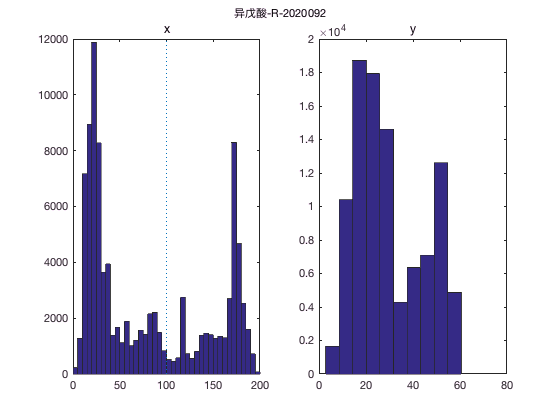

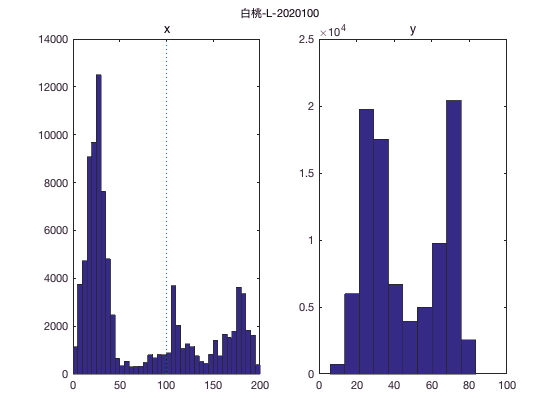

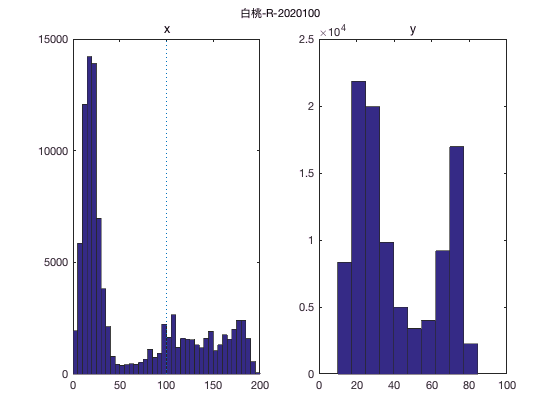

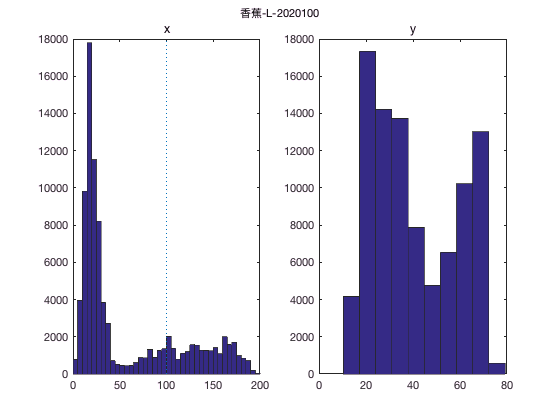

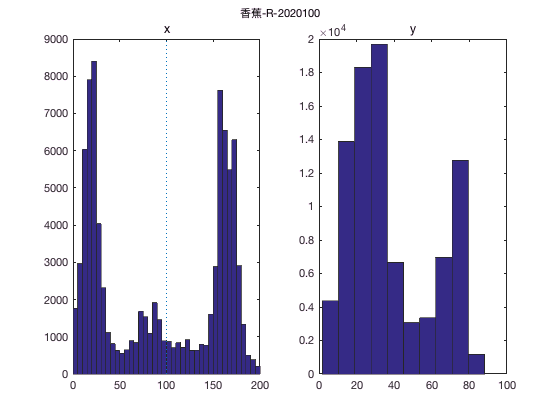

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 9.6766e+04
          df: 1
       edges: [0 100 200]
           O: [508038 239148]
           E: [373593 373593]


    90   110



pvalue = 0

st =     chi2stat: 1.0426e+05
          df: 1
       edges: [0 100 200]
           O: [485954 215517]
           E: [3.5074e+05 3.5074e+05]


    80   120



pvalue = 0

st =     chi2stat: 1.0752e+05
          df: 1
       edges: [0 100 200]
           O: [462082 196071]
           E: [3.2908e+05 3.2908e+05]


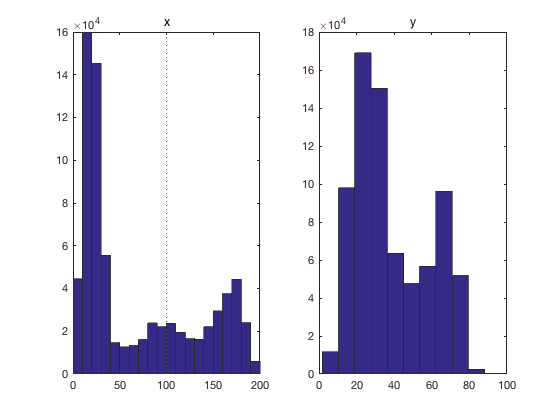


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

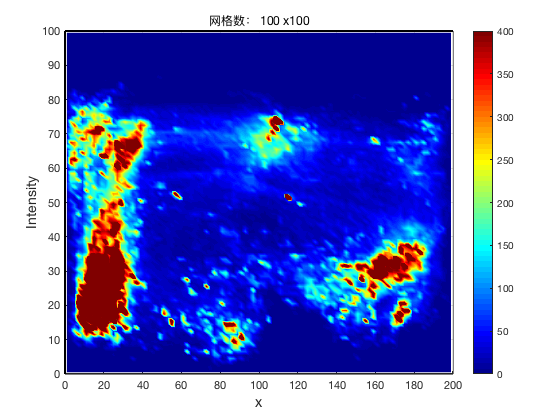

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 35.724367 秒。


## 合并odor两个条件

吲哚-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 1.4417e+04
          df: 1
       edges: [0 100 200]
           O: [100328 82447]
           E: [1.2428e+05 5.8500e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.4016e+04
          df: 1
       edges: [0 100 200]
           O: [94941 74565]
           E: [1.1743e+05 5.2078e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.2983e+04
          df: 1
       edges: [0 100 200]
           O: [90738 68081]
           E: [1.1151e+05 4.7314e+04]


异戊酸-L-2020092


   100   100



pvalue = 0

st =     chi2stat: 1.5904e+04
          df: 1
       edges: [0 100 200]
           O: [102737 85945]
           E: [1.2829e+05 6.0390e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7870e+04
          df: 1
       edges: [0 100 200]
           O: [98409 81392]
           E: [1.2456e+05 5.5241e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.9072e+04
          df: 1
       edges: [0 100 200]
           O: [90224 74832]
           E: [1.1588e+05 4.9172e+04]


白桃-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 3.5692e+04
          df: 1
       edges: [0 100 200]
           O: [92543 100515]
           E: [1.3127e+05 6.1791e+04]


    90   110



pvalue = 0

st =     chi2stat: 3.7124e+04
          df: 1
       edges: [0 100 200]
           O: [86649 92780]
           E: [1.2430e+05 5.5127e+04]


    80   120



pvalue = 0

st =     chi2stat: 3.8723e+04
          df: 1
       edges: [0 100 200]
           O: [82385 87845]
           E: [1.1952e+05 5.0713e+04]


香蕉-L-2020100


   100   100



pvalue = 0

st =     chi2stat: 4.2994e+03
          df: 1
       edges: [0 100 200]
           O: [111131 71540]
           E: [1.2420e+05 5.8467e+04]


    90   110



pvalue = 0

st =     chi2stat: 4.4075e+03
          df: 1
       edges: [0 100 200]
           O: [106935 65800]
           E: [1.1966e+05 5.3070e+04]


    80   120



pvalue = 0

st =     chi2stat: 4.1970e+03
          df: 1
       edges: [0 100 200]
           O: [103176 60872]
           E: [1.1518e+05 4.8872e+04]


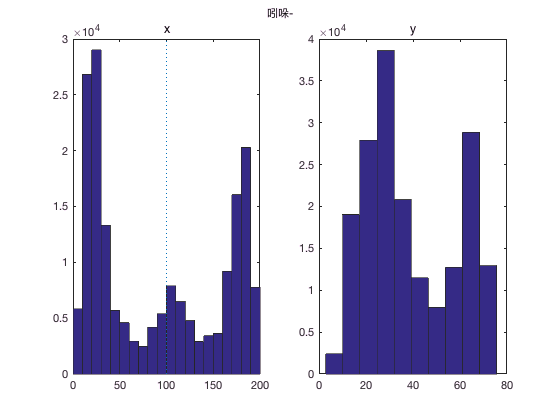

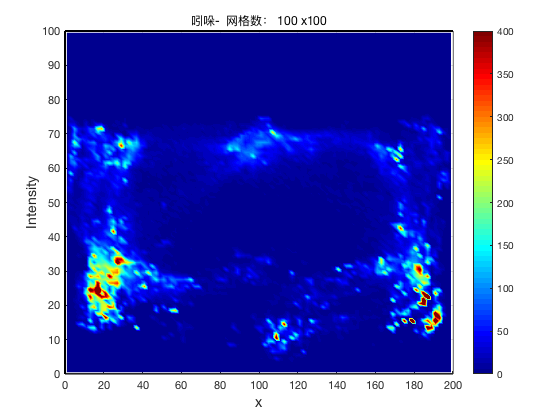

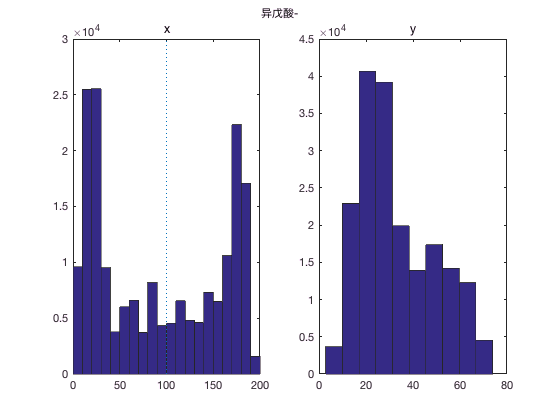

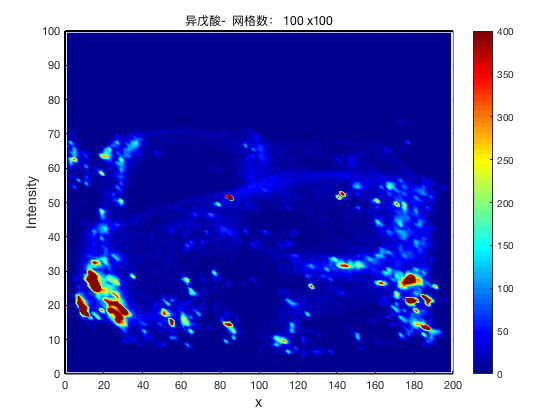

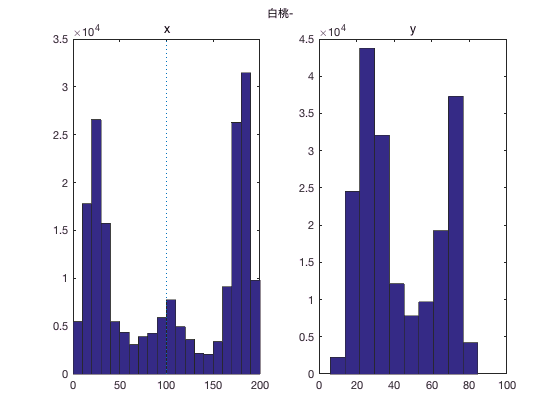

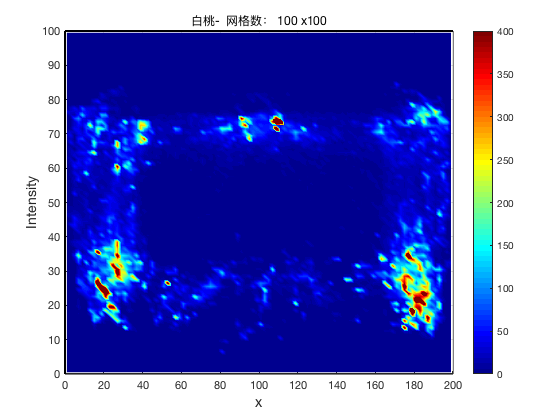

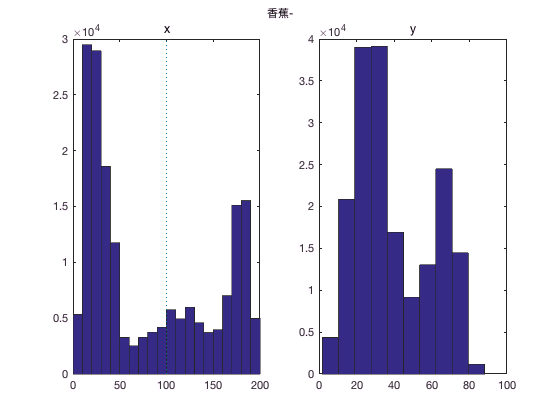

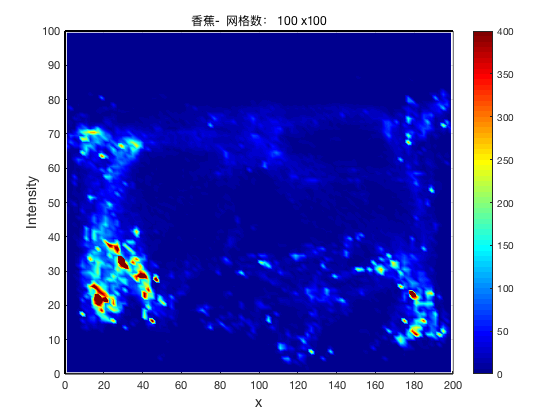

tic;
interval=10;
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1};data];

    % chisq test
    disp(conditions{odor-1})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 49.340493 秒。


## 合并odor两个条件的（只取前面一段时间）

   100   100



pvalue = 0

st =     chi2stat: 2.0486e+03
          df: 1
       edges: [0 100 200]
           O: [13861 7280]
           E: [1.0570e+04 1.0570e+04]


   100   100



pvalue = 7.1215e-112

st =     chi2stat: 505.1724
          df: 1
       edges: [0 100 200]
           O: [9962 7032]
           E: [8497 8497]


   100   100



pvalue = 7.8686e-69

st =     chi2stat: 307.4447
          df: 1
       edges: [0 100 200]
           O: [10112 12764]
           E: [11438 11438]


   100   100



pvalue = 0

st =     chi2stat: 5.3879e+03
          df: 1
       edges: [0 100 200]
           O: [14894 4636]
           E: [9765 9765]


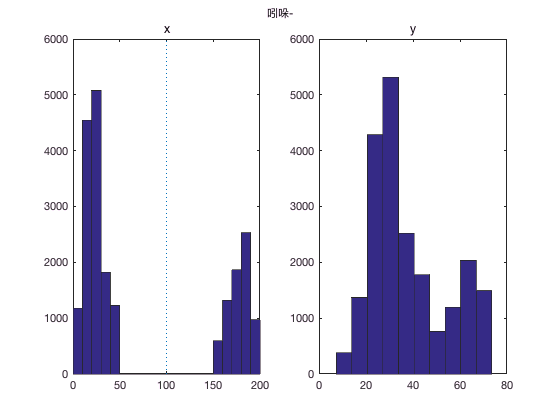

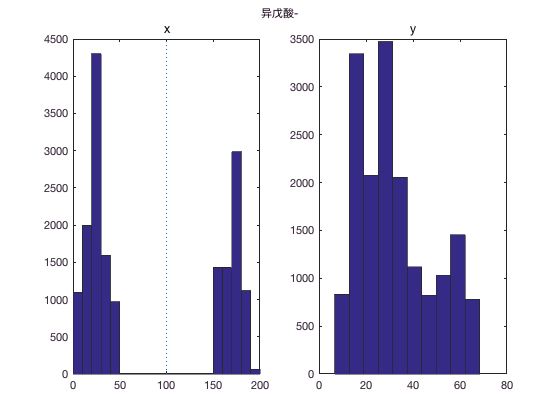

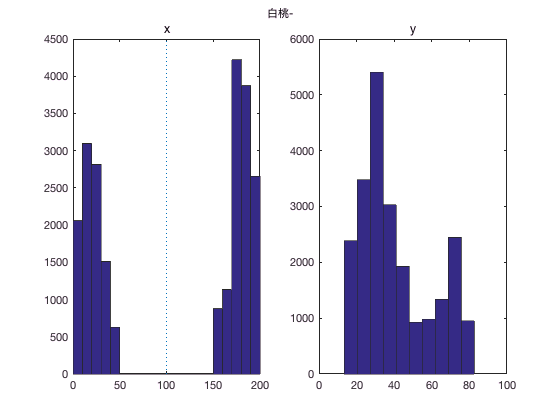

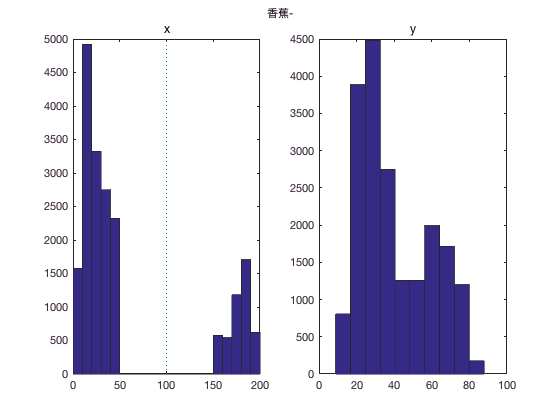

interval=10;
timeint=10;%minute
p1=1;
p2=timeint*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-2020100


-------------


100-100


        3852        2298
        4558        1592
        5340         810
        4427        1723
        3957        2193
        4946        1204
        4377        1773
        4666        1484
        5166         984
        4168        1982
        5495         655
        5055        1095
        4671        1479
        4462        1688
        3905        1047



   2.8883e+03



     0



-------------


-------------


90-110


        3672        2478
        4497        1653
        5271         879
        4361        1789
        3813        2337
        4802        1348
        4320        1830
        4591        1559
        4929        1221
        4036        2114
        5441         709
        4987        1163
        4593        1557
        4391        1759
        3835        1117



   2.9241e+03



     0



-------------


-------------


80-120


        3447        2703
        4462        1688
        5224         926
        4327        1823
        3697        2453
        4736        1414
        4289        1861
        4541        1609
        4587        1563
        3950        2200
        5334         816
        4902        1248
        4544        1606
        4350        1800
        3789        1163



   2.9674e+03



     0



-------------


-------------


70-130


        3325        2825
        4423        1727
        5177         973
        4270        1880
        3609        2541
        4691        1459
        4261        1889
        4485        1665
        4411        1739
        3889        2261
        5308         842
        4831        1319
        4502        1648
        4311        1839
        3750        1202



   3.0871e+03



     0



-------------


-------------


60-140


        3215        2935
        4388        1762
        5136        1014
        4228        1922
        3536        2614
        4619        1531
        4232        1918
        4439        1711
        4361        1789
        3823        2327
        5268         882
        4777        1373
        4465        1685
        4276        1874
        3719        1233



   3.1933e+03



     0



-------------


-------------


50-150


        3015        3135
        4354        1796
        5093        1057
        4187        1963
        3377        2773
        4408        1742
        4202        1948
        4377        1773
        4307        1843
        3760        2390
        5239         911
        4732        1418
        4419        1731
        4241        1909
        3685        1267



   3.5439e+03



     0



-------------


吲哚-R-2020093


-------------


100-100


        3289        2861
        2820        3330
        3607        2543
        3378        2772
        3898        2252
        3484        2666
        5099        1051
        4801        1349
        4975        1175
        3730        2420
        3083        3067
        4755        1395
        4718        1432
        3406        2744
        5397         226



   8.0582e+03



     0



-------------


-------------


90-110


        2995        3155
        2437        3713
        2865        3285
        3147        3003
        3304        2846
        3322        2828
        4895        1255
        4365        1785
        4849        1301
        3576        2574
        2614        3536
        4422        1728
        4485        1665
        2627        3523
        5379         244



   9.7961e+03



     0



-------------


-------------


80-120


        2661        3489
        2251        3899
        2401        3749
        2995        3155
        2812        3338
        3036        3114
        3895        2255
        3828        2322
        4773        1377
        3473        2677
        2451        3699
        4111        2039
        4112        2038
        2338        3812
        5366         257



   9.4868e+03



     0



-------------


-------------


70-130


        2201        3949
        1976        4174
        2234        3916
        2871        3279
        2712        3438
        2957        3193
        3126        3024
        3738        2412
        4703        1447
        3405        2745
        2330        3820
        4065        2085
        4011        2139
        2085        4065
        5354         269



   1.0611e+04



     0



-------------


-------------


60-140


        2061        4089
        1774        4376
        2124        4026
        2747        3403
        2542        3608
        2888        3262
        2980        3170
        3668        2482
        4634        1516
        3343        2807
        2191        3959
        4029        2121
        3937        2213
        1918        4232
        5343         280



   1.1507e+04



     0



-------------


-------------


50-150


        1917        4233
        1597        4553
        2027        4123
        2641        3509
        2403        3747
        2817        3333
        2864        3286
        3601        2549
        4560        1590
        3278        2872
        1951        4199
        3990        2160
        3863        2287
        1687        4463
        5330         293



   1.2605e+04



     0



-------------


异戊酸-L-2020092


-------------


100-100


        2629        3521
        3190        2960
        4452        1698
        5174         976
        5121        1029
        4473        1677
        3958        2192
        4960        1190
        5131        1019
        5881         269
        4443        1707
        5261         889
        4364        1786
        5201         949
        3298         731



   8.6371e+03



     0



-------------


-------------


90-110


        2027        4123
        2651        3499
        4356        1794
        4719        1431
        4982        1168
        4359        1791
        3668        2482
        4839        1311
        5040        1110
        5858         292
        4362        1788
        5054        1096
        4211        1939
        4837        1313
        3217         812



   1.0484e+04



     0



-------------


-------------


80-120


        1726        4424
        2208        3942
        4229        1921
        4686        1464
        4343        1807
        3839        2311
        2657        3493
        4717        1433
        4789        1361
        5846         304
        4314        1836
        4605        1545
        3475        2675
        4724        1426
        3172         857



   1.2354e+04



     0



-------------


-------------


70-130


        1453        4697
        1378        4772
        4147        2003
        4647        1503
        4264        1886
        3767        2383
        2426        3724
        4611        1539
        4649        1501
        5836         314
        4284        1866
        4521        1629
        3413        2737
        4438        1712
        3065         964



   1.5059e+04



     0



-------------


-------------


60-140


        1258        4892
        1201        4949
        4084        2066
        4619        1531
        4205        1945
        3718        2432
        2334        3816
        2551        3599
        3622        2528
        5824         326
        4258        1892
        4380        1770
        3365        2785
        4310        1840
        2776        1253



   1.4981e+04



     0



-------------


-------------


50-150


        1063        5087
        1060        5090
        3492        2658
        3145        3005
        4150        2000
        3668        2482
        2233        3917
        2434        3716
        3576        2574
        5815         335
        4230        1920
        4284        1866
        3312        2838
        4235        1915
        2672        1357



   1.4615e+04



     0



-------------


异戊酸-R-2020092


-------------


100-100


        2777        3373
        2781        3369
        3850        2300
        2930        3220
        4263        1887
        3610        2540
        3659        2491
        4607        1543
        2700        3450
        5989         161
        2895        3255
        4406        1744
        4509        1641
        3451        2699
        5064        1086
        5823         327
          38         115



   1.2054e+04



     0



-------------


-------------


90-110


        2549        3601
        2669        3481
        3700        2450
        2739        3411
        3875        2275
        3349        2801
        3556        2594
        4521        1629
        2513        3637
        5987         163
        2862        3288
        4299        1851
        4283        1867
        3302        2848
        4987        1163
        5811         339
          31         122



   1.2712e+04



     0



-------------


-------------


80-120


        2104        4046
        2543        3607
        2933        3217
        2471        3679
        3519        2631
        2875        3275
        3000        3150
        4410        1740
        1982        4168
        5981         169
        2826        3324
        4192        1958
        3906        2244
        3179        2971
        4924        1226
        5803         347
          29         124



   1.5185e+04



     0



-------------


-------------


70-130


        1744        4406
        2447        3703
        2817        3333
        2322        3828
        3457        2693
        2686        3464
        2782        3368
        4317        1833
        1843        4307
        5977         173
        2574        3576
        4093        2057
        3685        2465
        3031        3119
        4081        2069
        5796         354
          25         128



   1.5499e+04



     0



-------------


-------------


60-140


        1487        4663
        2279        3871
        2686        3464
        2252        3898
        3410        2740
        2537        3613
        2520        3630
        4218        1932
        1731        4419
        5974         176
        2433        3717
        3986        2164
        3505        2645
        2892        3258
        3736        2414
        5788         362
          17         136



   1.6498e+04



     0



-------------


-------------


50-150


        1310        4840
        2137        4013
        2567        3583
        2098        4052
        3359        2791
        2417        3733
        2378        3772
        4079        2071
        1652        4498
        5971         179
        2384        3766
        3891        2259
        3322        2828
        2745        3405
        3478        2672
        4639        1511
          14         139



   1.4093e+04



     0



-------------


白桃-L-2020100


-------------


100-100


        2831        3319
        3712        2438
        3479        2671
        3274        2876
        3595        2555
        3092        3058
        3410        2740
        4839        1311
        4274        1876
        4751        1399
        5201         949
        4646        1504
        4074        2076
        5339         811
        5185         965
          53           0



   7.2205e+03



     0



-------------


-------------


90-110


        2719        3431
        3610        2540
        3331        2819
        2830        3320
        3513        2637
        3006        3144
        3324        2826
        4812        1338
        4247        1903
        4697        1453
        5116        1034
        4473        1677
        4015        2135
        5326         824
        5073        1077
          53           0



   7.8186e+03



     0



-------------


-------------


80-120


        2530        3620
        3547        2603
        3226        2924
        2653        3497
        3461        2689
        2958        3192
        3262        2888
        4720        1430
        4228        1922
        4594        1556
        5078        1072
        4079        2071
        3959        2191
        5317         833
        5011        1139
          53           0



   8.0513e+03



     0



-------------


-------------


70-130


        2429        3721
        3488        2662
        3168        2982
        2574        3576
        3417        2733
        2913        3237
        3195        2955
        4688        1462
        4210        1940
        4556        1594
        5040        1110
        3943        2207
        3915        2235
        5309         841
        4971        1179
          53           0



   8.2924e+03



     0



-------------


-------------


60-140


        2355        3795
        3439        2711
        3125        3025
        2515        3635
        3379        2771
        2872        3278
        3140        3010
        4660        1490
        4194        1956
        4521        1629
        4991        1159
        3920        2230
        3876        2274
        5302         848
        4920        1230
          53           0



   8.4280e+03



     0



-------------


-------------


50-150


        2286        3864
        3376        2774
        3083        3067
        2463        3687
        3334        2816
        2830        3320
        3080        3070
        4634        1516
        4168        1982
        4474        1676
        4957        1193
        3895        2255
        3592        2558
        5295         855
        4878        1272
          53           0



   8.5818e+03



     0



-------------


白桃-R-2020100


-------------


100-100


        3639        2511
        3977        2173
        4468        1682
        3520        2630
        4049        2101
        4050        2100
        4877        1273
        4752        1398
        4849        1301
        3492        2658
        3897        2253
        4239        1911
        4742        1408
        4416        1734
        5116        1034
        3925        2225
        1959         396



   3.2315e+03



     0



-------------


-------------


90-110


        3563        2587
        3845        2305
        4397        1753
        3455        2695
        3971        2179
        3962        2188
        4784        1366
        4059        2091
        4801        1349
        3428        2722
        3832        2318
        4061        2089
        4679        1471
        4365        1785
        4204        1946
        3602        2548
        1790         565



   2.3006e+03



     0



-------------


-------------


80-120


        3514        2636
        3525        2625
        4325        1825
        3407        2743
        3896        2254
        3900        2250
        4681        1469
        3916        2234
        4768        1382
        3385        2765
        3783        2367
        3952        2198
        4586        1564
        4330        1820
        4168        1982
        3079        3071
        1742         613



   2.7346e+03



     0



-------------


-------------


70-130


        3464        2686
        3252        2898
        4284        1866
        3363        2787
        3838        2312
        3847        2303
        4569        1581
        3859        2291
        4738        1412
        3340        2810
        3716        2434
        3900        2250
        4440        1710
        4282        1868
        4130        2020
        3005        3145
        1727         628



   2.7879e+03



     0



-------------


-------------


60-140


        3427        2723
        3205        2945
        4252        1898
        3322        2828
        3793        2357
        3802        2348
        4411        1739
        3747        2403
        4711        1439
        3301        2849
        3626        2524
        3837        2313
        4420        1730
        4234        1916
        4105        2045
        2962        3188
        1711         644



   2.7227e+03



     0



-------------


-------------


50-150


        3387        2763
        3144        3006
        4220        1930
        3281        2869
        3741        2409
        3756        2394
        4293        1857
        3705        2445
        4681        1469
        3262        2888
        3583        2567
        3733        2417
        4399        1751
        4195        1955
        4077        2073
        2921        3229
        1694         661



   2.7034e+03



     0



-------------


香蕉-L-2020100


-------------


100-100


        4055        2095
        4681        1469
        4305        1845
        4719        1431
        3778        2372
        4417        1733
        4324        1826
        4365        1785
        4647        1503
        4838        1312
        4629        1521
        4902        1248
        4599        1551
        4776        1374
        5186         964
         211           0



   1.5369e+03



  5.7196e-319



-------------


-------------


90-110


        3732        2418
        4589        1561
        4027        2123
        4573        1577
        3560        2590
        4301        1849
        4032        2118
        4053        2097
        4597        1553
        4667        1483
        4360        1790
        4822        1328
        4471        1679
        4666        1484
        5149        1001
         211           0



   2.0973e+03



     0



-------------


-------------


80-120


        3331        2819
        4250        1900
        3882        2268
        4495        1655
        3439        2711
        4240        1910
        3769        2381
        3977        2173
        4566        1584
        4608        1542
        4194        1956
        4777        1373
        4368        1782
        4365        1785
        5131        1019
         211           0



   2.6008e+03



     0



-------------


-------------


70-130


        3198        2952
        4167        1983
        3841        2309
        4427        1723
        3326        2824
        4161        1989
        3484        2666
        3904        2246
        4508        1642
        4545        1605
        4062        2088
        4705        1445
        4272        1878
        3938        2212
        5112        1038
         211           0



   2.9122e+03



     0



-------------


-------------


60-140


        3118        3032
        4123        2027
        3799        2351
        4379        1771
        3242        2908
        4072        2078
        3359        2791
        3833        2317
        4471        1679
        4501        1649
        3997        2153
        4652        1498
        4199        1951
        3744        2406
        5096        1054
         211           0



   3.1264e+03



     0



-------------


-------------


50-150


        3047        3103
        4081        2069
        3764        2386
        4330        1820
        3173        2977
        3995        2155
        3252        2898
        3722        2428
        4436        1714
        4453        1697
        3945        2205
        4603        1547
        4138        2012
        3679        2471
        5073        1077
         211           0



   3.2717e+03



     0



-------------


香蕉-R-2020100


-------------


100-100


        2489        3661
        3314        2836
        2978        3172
        3271        2879
        3617        2533
        4351        1799
        3601        2549
        3000        3150
        3500        2650
        3939        2211
        3110        3040
        3901        2249
        3853        2297
         693        5457
        1894        2216



   6.6443e+03



     0



-------------


-------------


90-110


        2376        3774
        3021        3129
        2798        3352
        2851        3299
        3400        2750
        4224        1926
        3346        2804
        2887        3263
        3272        2878
        3874        2276
        3000        3150
        3858        2292
        3713        2437
         660        5490
        1887        2223



   6.3286e+03



     0



-------------


-------------


80-120


        2275        3875
        2658        3492
        2663        3487
        2201        3949
        2967        3183
        4126        2024
        3192        2958
        2642        3508
        2871        3279
        3807        2343
        2865        3285
        3832        2318
        3541        2609
         636        5514
        1881        2229



   6.4524e+03



     0



-------------


-------------


70-130


        2189        3961
        2022        4128
        2194        3956
        1657        4493
        2434        3716
        4020        2130
        3025        3125
        2548        3602
        2673        3477
        3736        2414
        2803        3347
        3811        2339
        3325        2825
         618        5532
        1876        2234



   7.3094e+03



     0



-------------


-------------


60-140


        2107        4043
        1863        4287
        2040        4110
        1416        4734
        2313        3837
        3649        2501
        2895        3255
        2461        3689
        2547        3603
        3672        2478
        2752        3398
        3790        2360
        3223        2927
         597        5553
        1870        2240



   7.2122e+03



     0



-------------


-------------


50-150


        2035        4115
        1739        4411
        1930        4220
        1294        4856
        2213        3937
        3547        2603
        2786        3364
        2387        3763
        2482        3668
        3620        2530
        2691        3459
        3767        2383
        3122        3028
         572        5578
        1805        2305



   7.3531e+03



     0



-------------


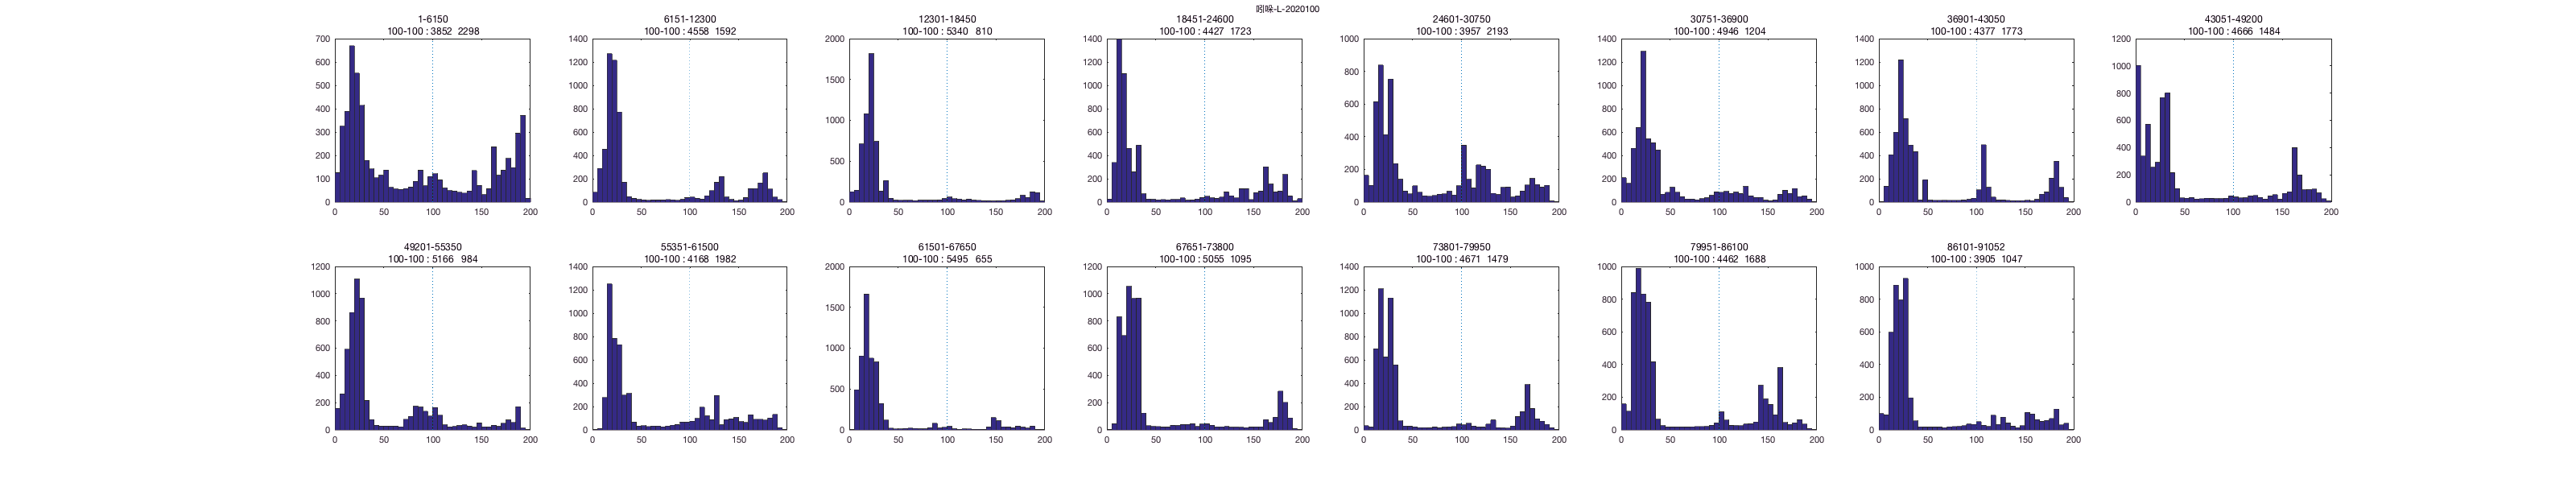

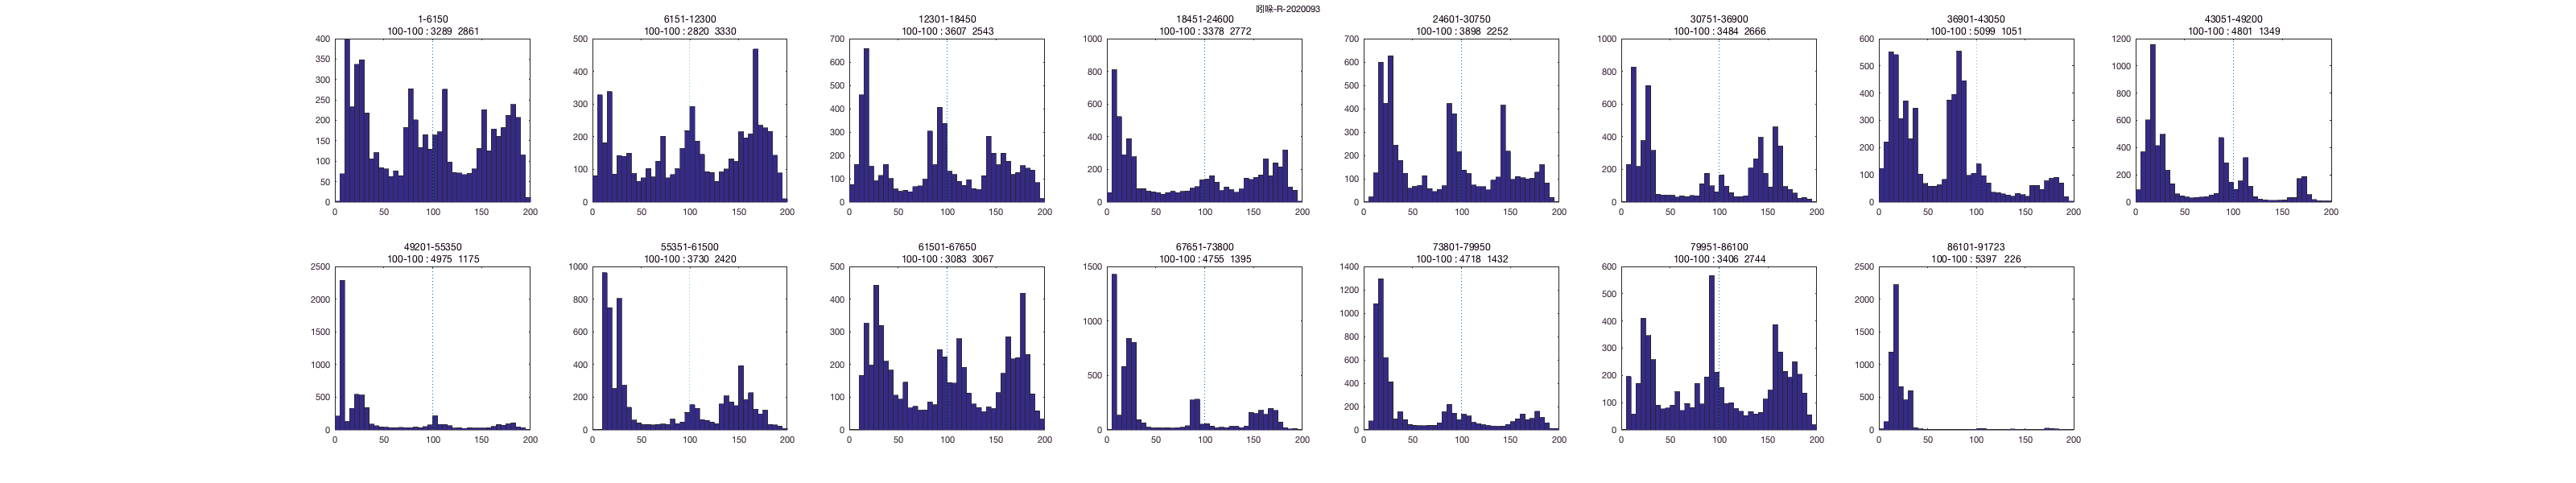

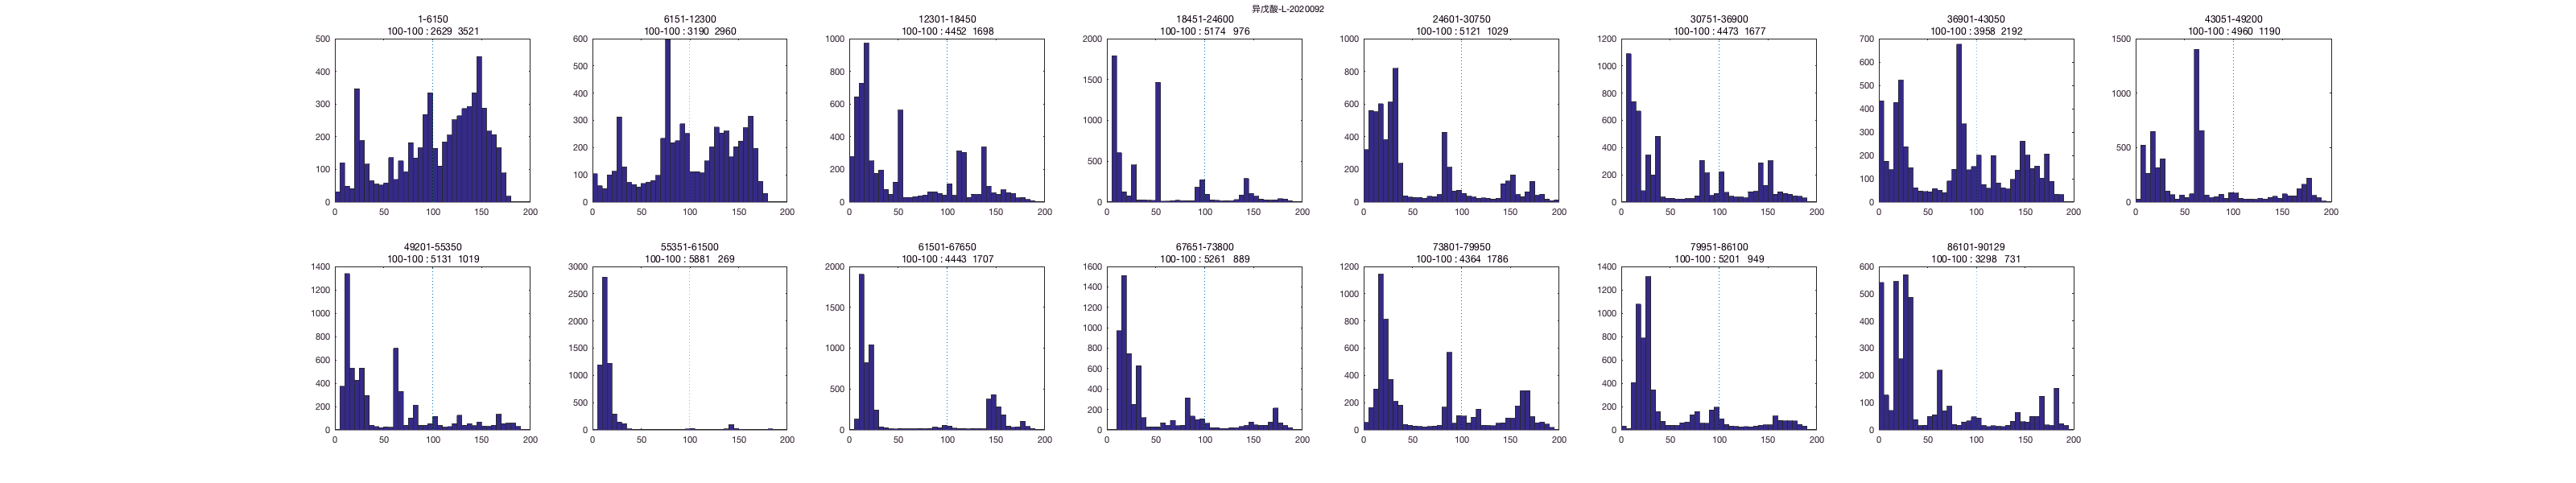

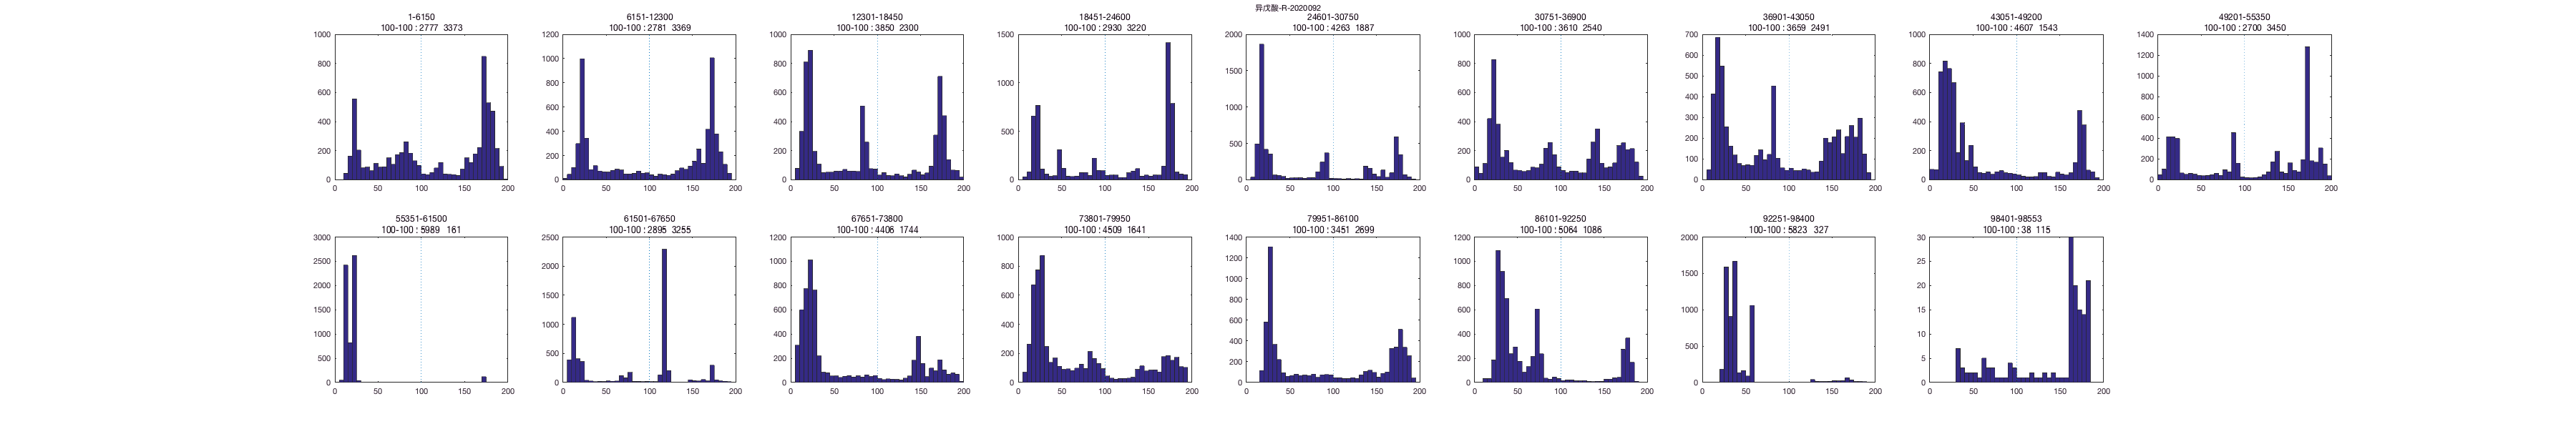

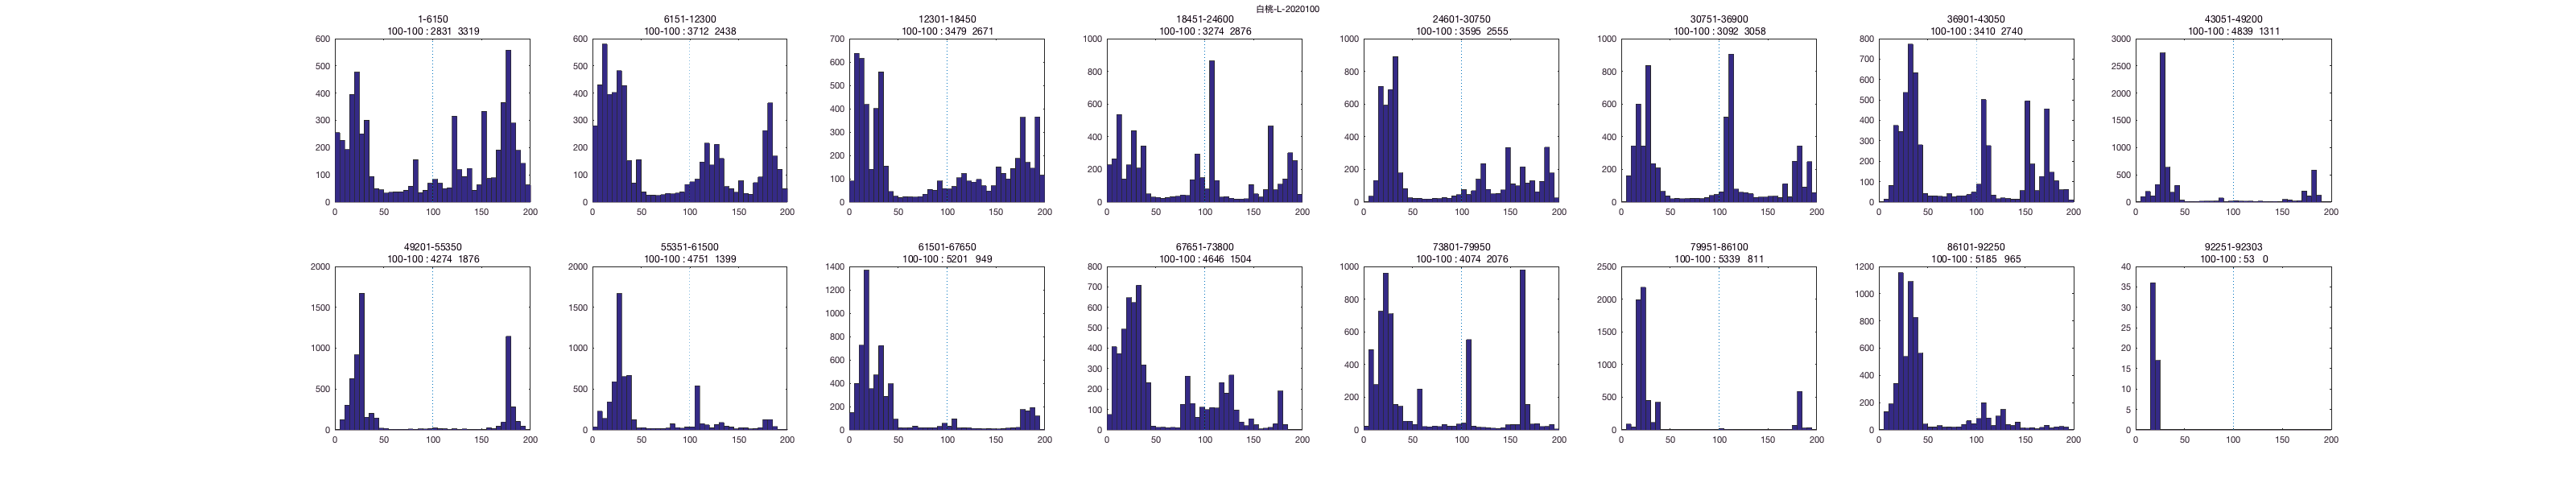

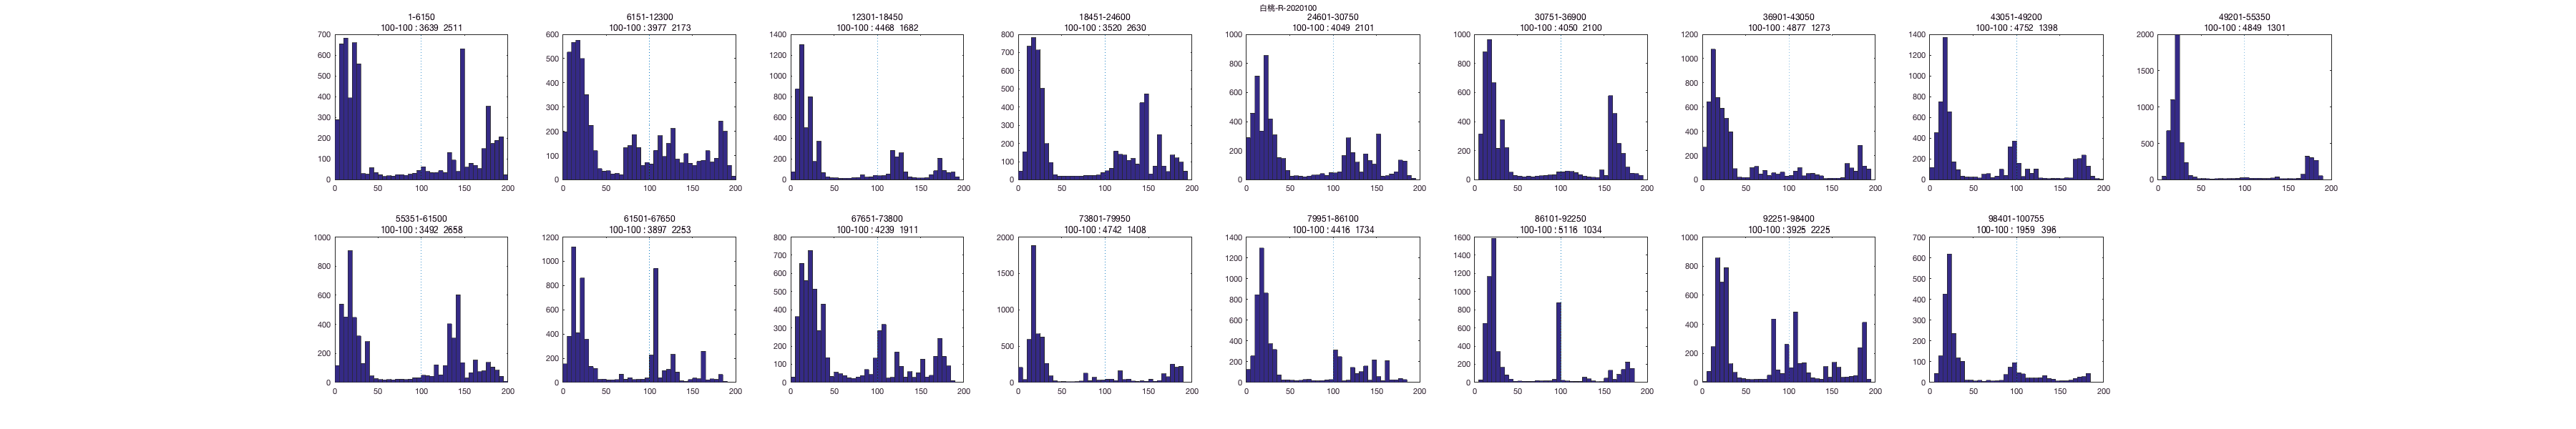

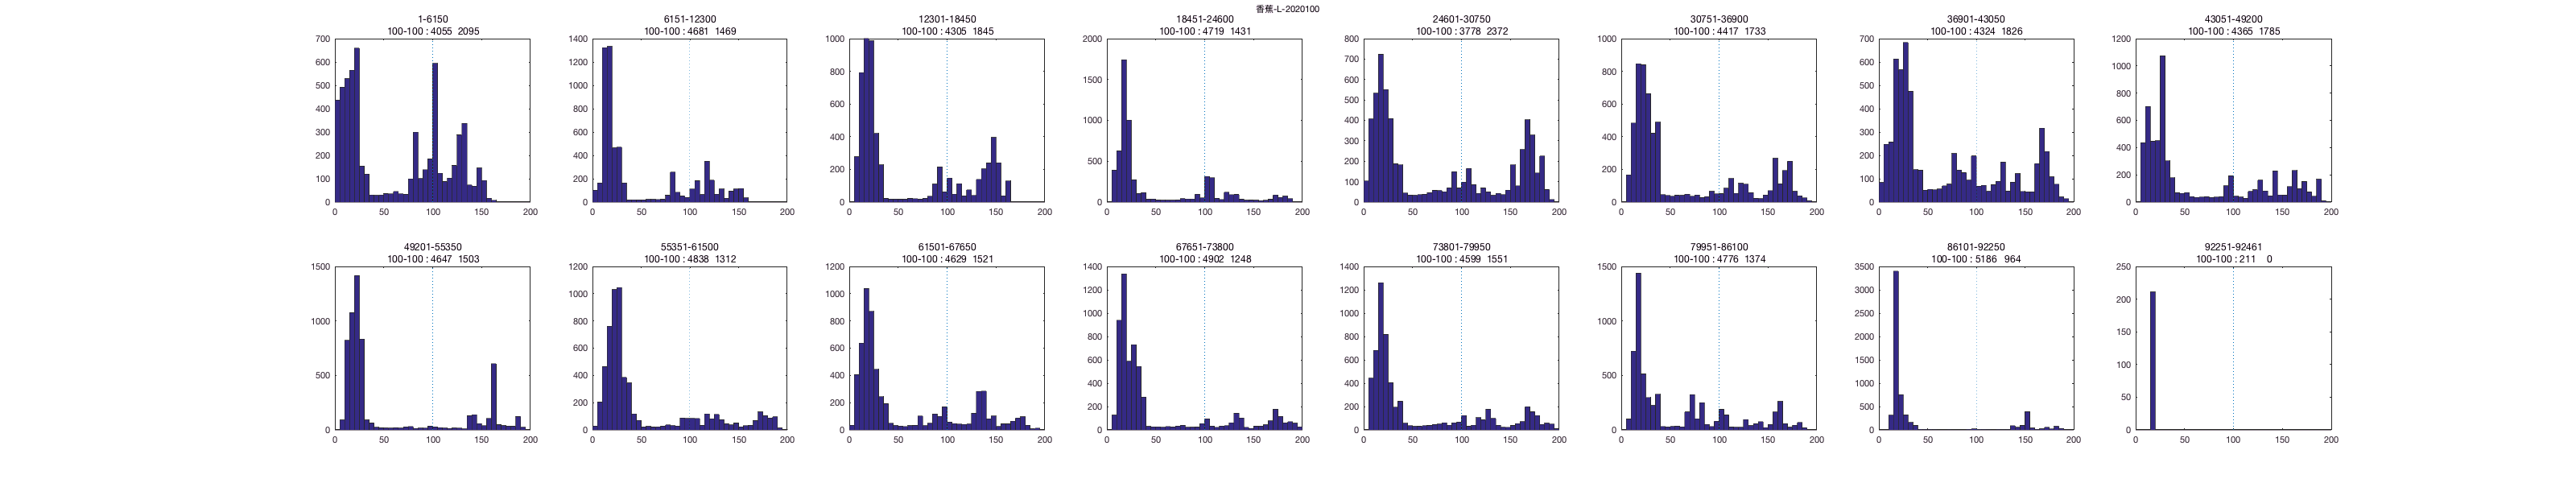

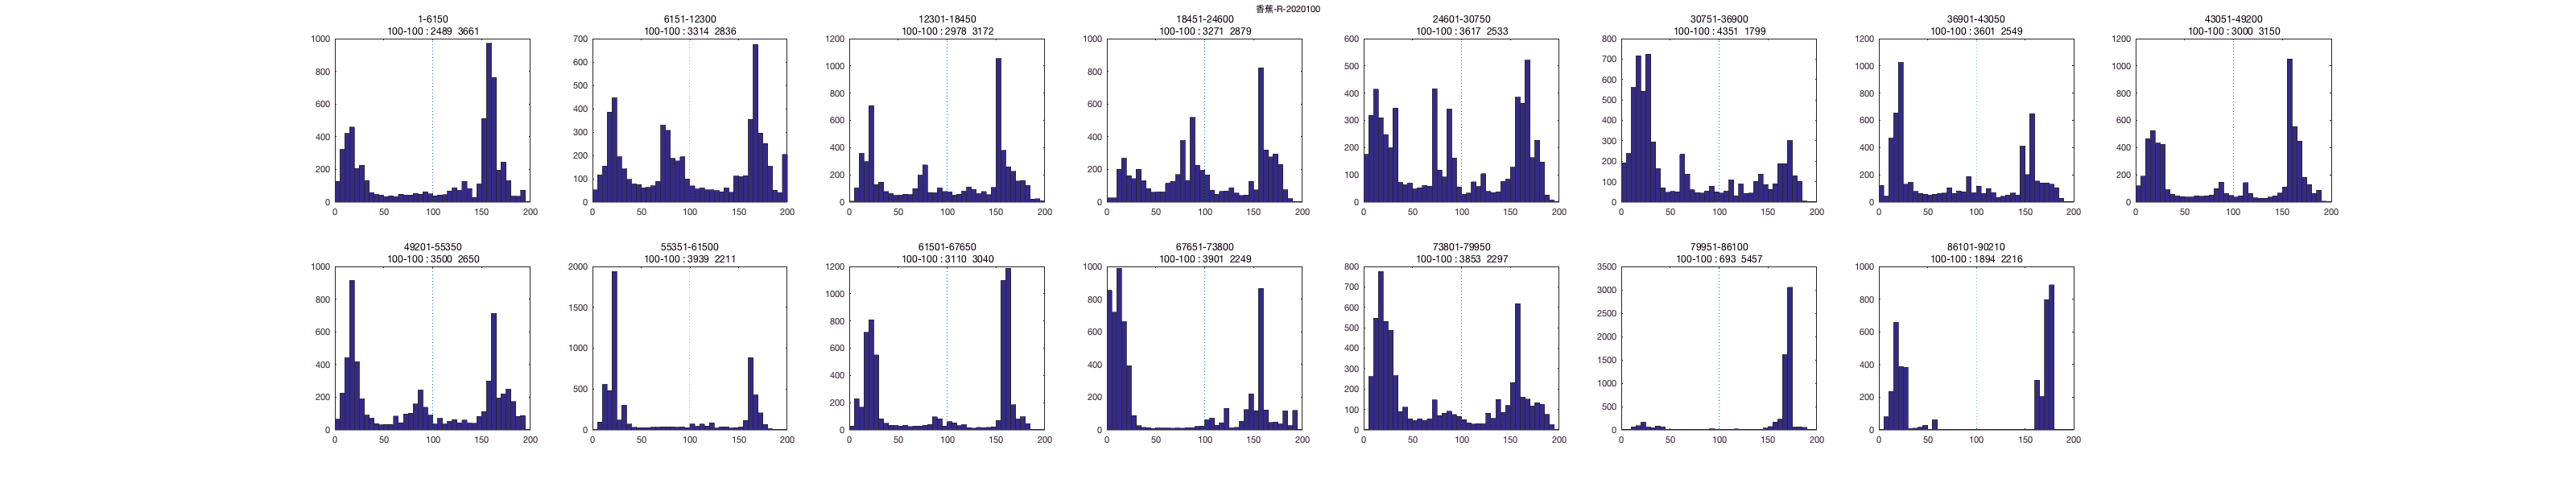

timeint=4.1;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')

    end
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end